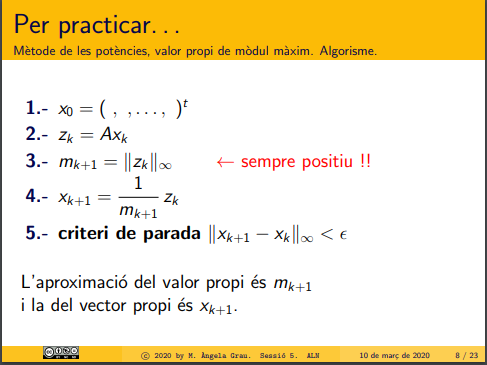

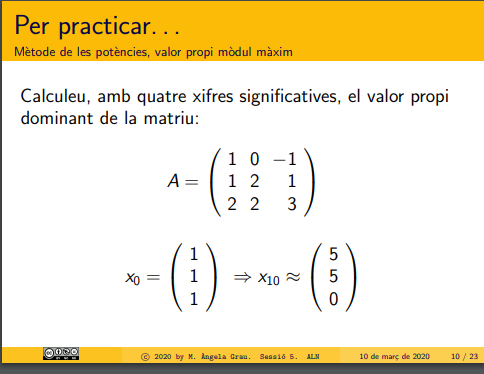

i = 0;
xk = [1 1 1]'; % [ - 1 1 2]
A = [1 0 -1; 1 2 1;2 2 3];
while (i<10)
    zk = A*xk;
    mkmas1 = norm(zk,'inf') %valor propi
    if mkmas1 < 0 
        mkmas1 = mkmas1*(-1)
    end
    xkmas1 = (1/mkmas1)*zk;
    if norm(xkmas1-xk, 'inf') < eps
        display('fi');
        break;
    end
    %sigui valor propi mantenir A*v = lambda*v  
    %if norm(A*xkmas1- norm(    )*xkmas1)<eps
    %    display('fi');
    %end
    i = i +1;
    xk = xkmas1;
end
vap = mkmas1
vep = xkmas1
residu = norm(A*vep-vap*vep);

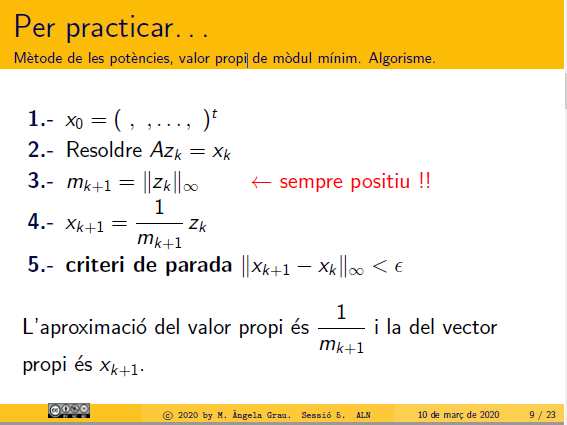

i = 0;
xk = [0 0 1]'; % [ - 1 1 2]
A = [1 0 -1; 1 2 1;2 2 3];
while (i<10)
    zk = A\xk;
    mkmas1 = norm(zk,'inf') %valor propi
    if mkmas1 < 0 
        mkmas1 = mkmas1*(-1)
    end
    xkmas1 = (1/mkmas1)*zk;
    if norm(xkmas1-xk, 'inf') < eps
        display('fi');
        break;
    end
    %sigui valor propi mantenir A*v = lambda*v  
    %if norm(A*xkmas1- norm(    )*xkmas1)<eps
    %    display('fi');
    %end
    i = i +1;
    xk = xkmas1;
end
vap = 1/mkmas1
vep = xkmas1
residu = norm(A*vep-vap*vep);

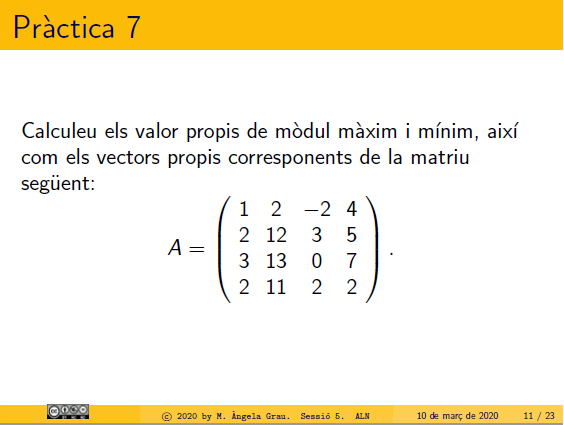

A= [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
xk = [1 0 0 1]';
% maxim
while (true)
    zk = A*xk;
    mkmas1 = norm(zk,'inf') %valor propi
    if mkmas1 < 0 
        mkmas1 = mkmas1*(-1);
    end
    xkmas1 = (1/mkmas1)*zk;
    if norm(xkmas1-xk, 'inf') < eps
        display('fi');
        break;
    end
    %sigui valor propi mantenir A*v = lambda*v  
    %if norm(A*xkmas1- norm(    )*xkmas1)<eps
    %    display('fi');
    %end
    i = i +1;
    xk = xkmas1;
end
i
vap = mkmas1
vep = xkmas1
% minim
A= [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
xk = [1 0 0 1]';
i = 0;
while (true)
    zk = A\xk;
    mkmas1 = norm(zk,'inf'); %valor propi
    if mkmas1 < 0 
        mkmas1 = mkmas1*(-1);
    end
    xkmas1 = (1/mkmas1)*zk;
    if norm(xkmas1-xk, 'inf') < eps
        display('fi');
        break;
    end
    %sigui valor propi mantenir A*v = lambda*v  
    %if norm(A*xkmas1- norm(    )*xkmas1)<eps
    %    display('fi');
    %end
    i = i +1;
    xk = xkmas1;
end
i
vap = 1/mkmas1
vep = xkmas1

# FALTA FER

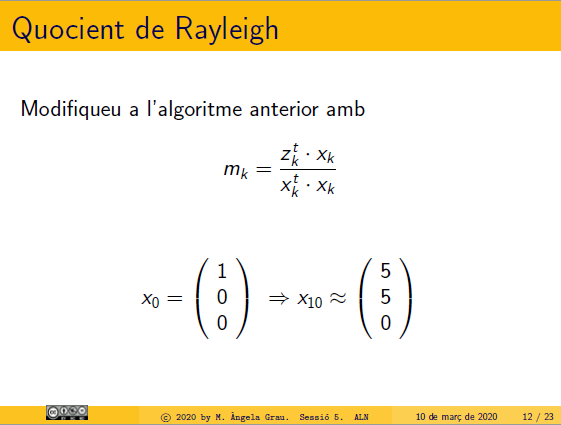

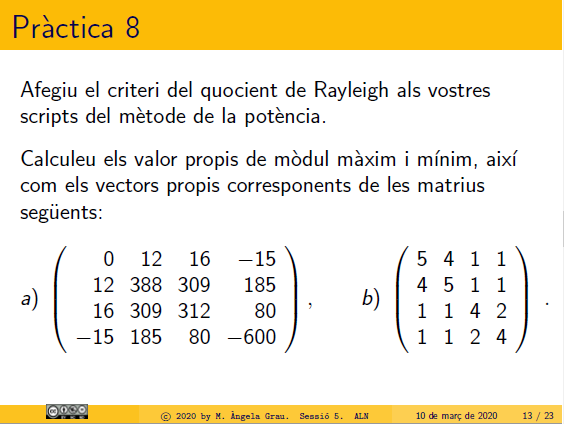

A= [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
xk = [1 0 0 1]';
while (true)
    zk = A*xk;
    mkmas1 = (xk'*zk)/(xk'*xk); %valor propi
    if mkmas1 < 0 
        mkmas1 = mkmas1*(-1);
    end
    xkmas1 = (1/mkmas1)*zk;
    if norm(xkmas1-xk, 'inf') < eps
        display('fi');
        break;
    end
    i = i +1;
    xk = xkmas1;
end
i
vap = mkmas1
vep = xkmas1

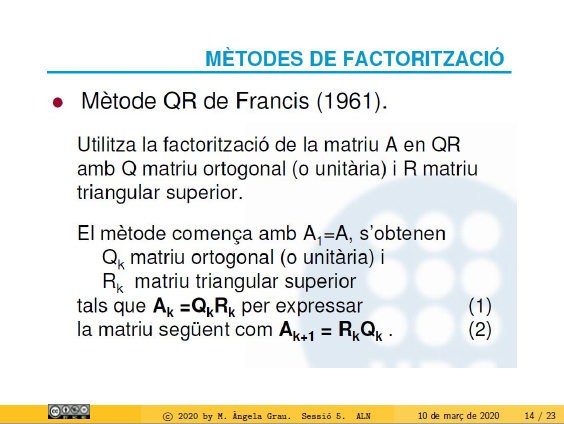

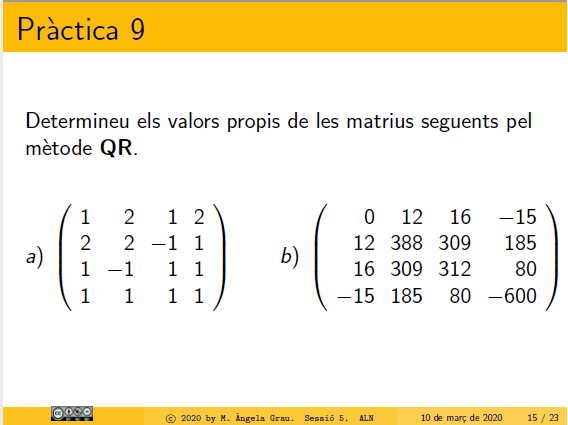

%Les diagones de la matriu Ak son els valors propis de la matriu A
A = [1 2 1 2; 2 2 -1 1; 1 -1 1 1; 1 1 1 1];
Ak = A;
k = 0;
while k < 150 && norm(tril(A,-1),'inf') > eps
    [Qk, Rk] = qr(Ak);
    Ak = Rk*Qk;%Ak+1 = Rk*Qk
    k = k +1;
end
Ak

%Diferent forma de calcular els valors propis
roots(poly(A))

# Valors Singulars - SVD 

**Practica 11**

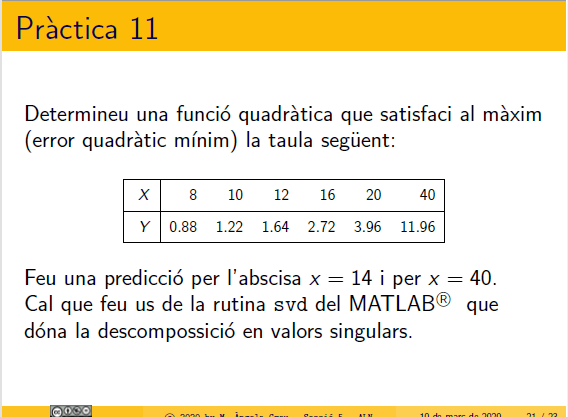

x = [ 8 10 12 16 20 40]';
y =  [0.88 1.22 1.64 2.72 3.96 11.96]';

A= [x.^2, x, ones(size(x))];
b = [0.88 1.22 1.64 2.72 3.96 11.96]';
solucio1 = A\b

solucio1 =    0.004532157967899
   0.130749352434920
  -0.516647397965770



%Equacions normals(proyeccio ortogonal)
solucio2 = (A'*A)\(A'*b)

solucio2 =    0.004532157967899
   0.130749352434922
  -0.516647397965784



%%%%%%%%%%% Valors Singulars %%%%%%%%%%%%%%
%A = U*S*V' 
%Apseudoinversa = V'*Spseudoinversa*U
[U, S, V] = svd(A);

valors_singulars_S = sqrt(eig(A'*A));

V'*V; %identitat
U'*U; %identitat
pinv(A); %Apseudoinversa

solucio3 = pinv(A)*y

solucio3 =    0.004532157967899
   0.130749352434921
  -0.516647397965775


**Practica 10**

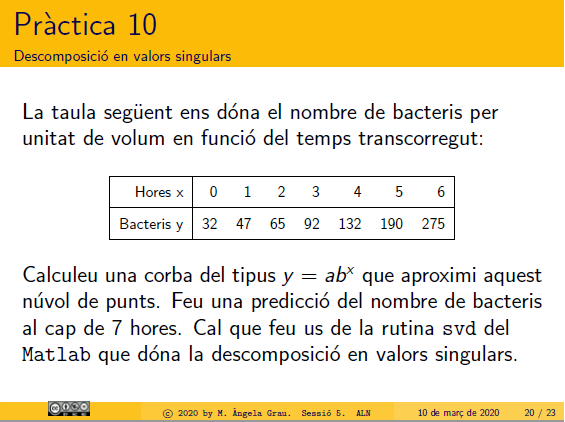

**Conversio lineal**

%y = a*(b^x) <-> log y = log a + x*logb

A = [0 1; 1 1; 2 1; 3 1; 4 1; 5 1; 6 1];
b = [log(32) log(47) log(65) log(92) log(132) log(190) log(275)]';
R = (A\b)'

R =    0.355545470649719   3.470314508603399


b = exp(1)^(R(1))

b =    1.426958806179804


a = exp(1)^(R(2))

a =   32.146851316317473


y = a*(b^7)

y =      3.872741356647434e+02
